tic
% 1. You'll need to update the inelow to folder locations.
local_save_directory =  "/Users/rikkimasson/Downloads/bladeRAD_data";
%"C:\Users\uceerm6\OneDrive - University College London\Documents\Radar_Data\beasley_bladeRAD\"; % Local directory containing the radar data.
repo_directory = "/Users/rikkimasson/Documents/GitHub";
% "C:\Users\uceerm6\OneDrive - University College London\Documents\GitHub";

% 2. Processing Flags - choose whether to
process_active_flag = true;
process_passive_flag = true;
ground_truth_flag = false;

% 3. Select the experiment you wish to process
experiment_number = 2;

if ismac
        bracket = "/";
    elseif isunix
        disp('isunix repo directory not defined')
    elseif ispc
        bracket = "\";
    else
        disp('Platform not supported')
end

% adds paths to generic functions
if ismac
    addpath(repo_directory + '/bladeRAD-Rikki/generic_scripts/matlab',...
    repo_directory + '/bladeRAD-Rikki/generic_scripts/matlab/CFAR/',...
    repo_directory + '/bladeRAD-Rikki/generic_scripts',...
    repo_directory + '/bladeRAD-Rikki/generic_scripts/ref_signals/')
    elseif isunix
            disp('isunix repo directory not defined')
    elseif ispc
        addpath(repo_directory + '\bladeRAD-Rikki\generic_scripts\matlab',...
        repo_directory + '\bladeRAD-Rikki\generic_scripts\matlab\CFAR\',...
        repo_directory + '\bladeRAD-Rikki\generic_scripts',...
        repo_directory + '\bladeRAD-Rikki\generic_scripts\ref_signals\')
    else
        disp('Platform not supported')
end

for i=experiment_number

## Load .mat file containing experiment setup parameters

    mat_file_name = local_save_directory + i + bracket + "Experimental Configuration.mat";
    load(mat_file_name);
    exp_dir = local_save_directory + i + bracket;

## Load Ground Truth Data

    if ground_truth_flag == true
        mat_file_name = local_save_directory  + i + bracket +"geode1.mat";
        load(mat_file_name);
        
        gt.time_offset = 280-14; % offset between start time of radar and gps recording
        gt.range_offset = 8; % Range fudge factor between radar and gps
        gt.range = geode1.target_range(gt.time_offset:gt.time_offset+capture_duration) + gt.range_offset;
        gt.sog = geode1.SoG(gt.time_offset :gt.time_offset +capture_duration);
        
        % Interpolate to number of active radar pulses
        old_sample_points = 0:capture_duration;
        active_pulses_sample_points = 1:active.number_pulses;
        gt.pulses_interp_range = interp1(old_sample_points,gt.range,active_pulses_sample_points/1000,'linear');
    end

## FMCW Processing and Print RTI

adc_max = 0.6978

adc_rms = 0.3077

dbfs = -3.6135

dbm = 2.7729

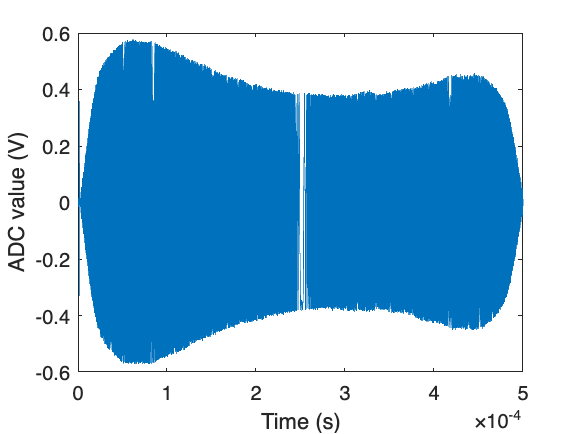

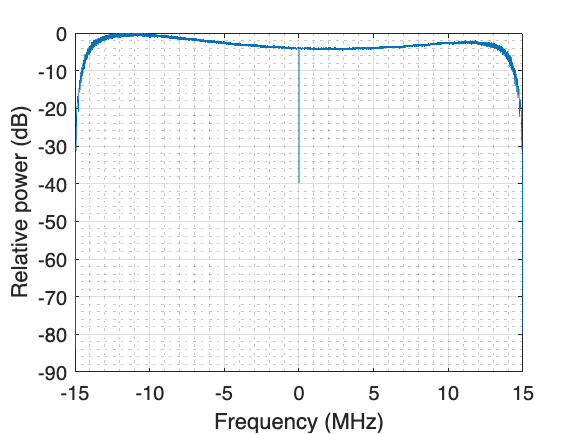

deramp_data = 19.8384

Filter_and_Decimation_time = 42.4304

active = struct with fields:
                          Fs: 30000000
              pulse_duration: 1.0000e-03
                          Bw: 30000000
                          Fc: 2.4400e+09
                     Tx_gain: 66
                    Rx1_gain: 0
                    Rx2_gain: 0
                      Tx_SDR: 1
                      Rx_SDR: 2
                   max_range: 1000
                         PRF: 1000
                       slope: 3.0000e+10
                       F_Max: 15000000
             sample_duration: 3.3333e-08
                      active: [1×1 struct]
               number_pulses: 15000
            number_cap_samps: 450000000
                     RF_freq: 2440
                        Bw_M: 30
    decimation_factor_actual: 150
                  range_bins: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 … ]

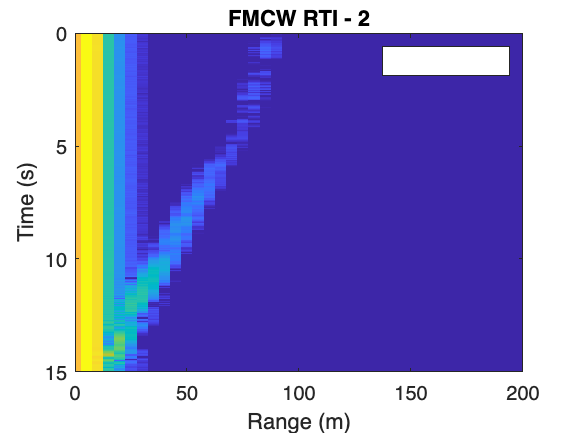

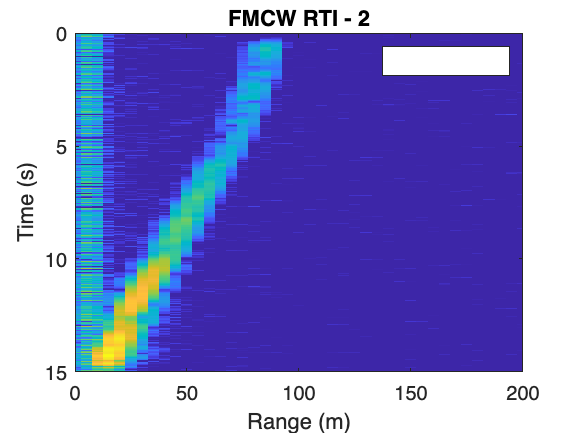

fig =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [616 498 560 420]
       Units: 'pixels'

  Show all properties


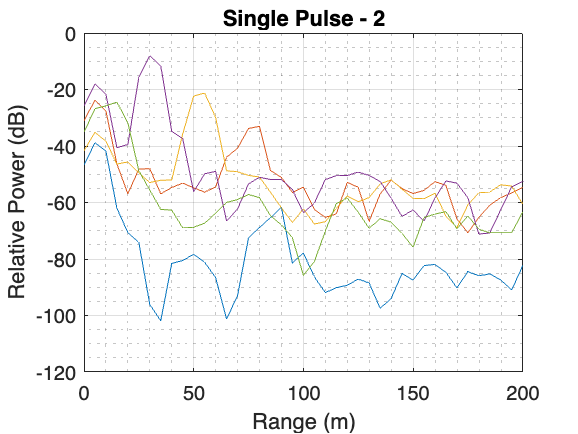

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-50 0]
    FontSize: 9
    Position: [0.8494 0.1095 0.0286 0.8155]
       Units: 'normalized'

  Show all properties


c =   ColorBar (Norm Power (dB)) with properties:

    Location: 'eastoutside'
      Limits: [-50 0]
    FontSize: 9
    Position: [0.8494 0.1095 0.0286 0.8155]
       Units: 'normalized'

  Show all properties


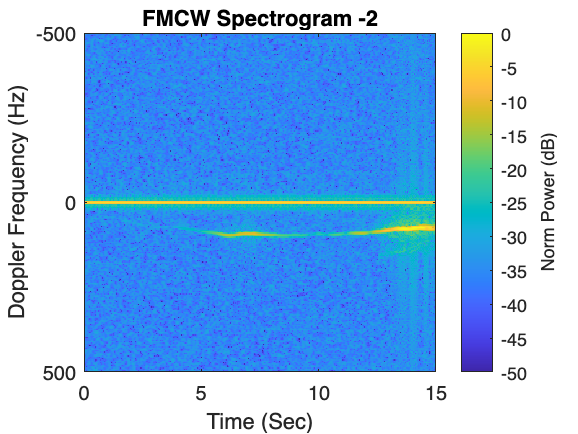

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-50 0]
    FontSize: 9
    Position: [0.8494 0.1095 0.0286 0.8155]
       Units: 'normalized'

  Show all properties


c =   ColorBar (Norm Power (dB)) with properties:

    Location: 'eastoutside'
      Limits: [-50 0]
    FontSize: 9
    Position: [0.8494 0.1095 0.0286 0.8155]
       Units: 'normalized'

  Show all properties


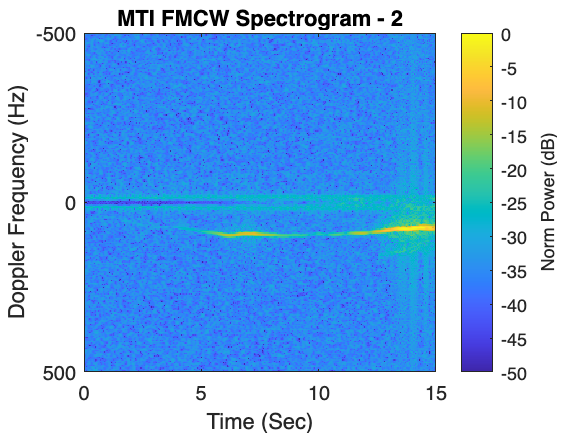

    if process_active_flag == true
        % load refsig for deramping
        refsig = load_refsig(active.Bw_M,active.Fs,active.Fc,active.pulse_duration);
        % load Signal, Mix and Dermap Signal
        file_location = exp_dir + 'active_' + Experiment_ID;
        lp_filter = true;
        [max_range_actual,deramped_signal,active.decimation_factor_actual] = deramp_and_decimate(file_location,active.max_range,refsig,capture_duration,active.number_pulses,active.Fs,active.slope,lp_filter);
        save(exp_dir + 'deramped_signal','deramped_signal')
        
        % Window and FFT Signal
        % window signal
        w = window('blackman',size(deramped_signal,1));
        windowed_signal = deramped_signal.*w;
        % fft signal
        zero_padding = 1; % 1 = none; 2 = 100%
        processed_signal = fft(windowed_signal,size(windowed_signal,1)*zero_padding);
        beat_frequncies = processed_signal(1:(size(processed_signal,1)/2),:); % keep +ve beat frequencies
        
        % MTI Filtering
        % Single Delay Line Filter
        MTI_Data = zeros(size(beat_frequncies));
        active.range_bins = size(MTI_Data,1);
        for i=2:active.number_pulses
            MTI_Data(:,i) = beat_frequncies(:,i)-beat_frequncies(:,i-1);
        end
        % IIR Filter
        [b, a] = butter(10, 0.021, 'high');
        for i=1:active.range_bins
            MTI_Data(i,:) = filtfilt(b,a,beat_frequncies(i,:));
        end
        
        % Derive range and time axis
        active.n_range_bins = size(beat_frequncies,1);
        active.range_bins = 1:active.n_range_bins;
        active.fftfrequncies =fftfreq(size(processed_signal,1),1/(active.Fs/active.decimation_factor_actual)); % possible beat frequencies
        active.slope = active.Bw/active.pulse_duration;
        ranges = (active.fftfrequncies*C)/(2*active.slope); % calculate true range bin size
        active.range_axis = ranges(1:(size(ranges,2)/2)); % truncate to only +ve beat frequencies
        active.range_bin_size = ranges(2)
        active.time_axis = linspace(0,size(processed_signal,2)*active.pulse_duration,size(processed_signal,2));
        
        % Plot RTI
        RTI_plot= transpose(20*log10(abs(beat_frequncies./max(beat_frequncies(:)))));
        figure
        fig = imagesc(active.range_axis,active.time_axis,RTI_plot,[-50,0]); hold on;
        if ground_truth_flag == true
            plot(gt.pulses_interp_range,active.time_axis,'-r', 'LineWidth', 2);
        end
        ylabel('Time (s)');xlabel('Range (m)');legend('Target Ground Truth') % Ground Truth data not provided
        title("FMCW RTI - " + Experiment_ID)
        xlim([0 200])
        fig_name = exp_dir + "RTI -" + Experiment_ID + ".jpg";
        saveas(fig,fig_name,'jpeg')
        saveas(fig,fig_name)
        
        % Plot MTI RTI
        RTI_plot= transpose(20*log10(abs(MTI_Data./max(MTI_Data(:)))));
        figure
        fig = imagesc(active.range_axis,active.time_axis,RTI_plot,[-50,0]); hold on;
        if ground_truth_flag == true
            plot(gt.pulses_interp_range,active.time_axis,'-r', 'LineWidth', 2);
        end
        ylabel('Time (s)');xlabel('Range (m)');legend('Target Ground Truth') % Ground Truth data not provided
        title("FMCW RTI - " + Experiment_ID)
        xlim([0 200])
        fig_name = exp_dir + "RTI -" + Experiment_ID + ".jpg";
        saveas(fig,fig_name,'jpeg')
        saveas(fig,fig_name)
        
        % Plot series of pulses
        fig = figure
        ranges_2_plot = floor(linspace(1,active.number_pulses,5));
        for i = ranges_2_plot
            plot(active.range_axis,RTI_plot(i,:));
            hold on
        end
        title("Single Pulse - " + Experiment_ID);
        xlim([0 200])
        grid on; grid minor;
        ylabel('Relative Power (dB)')
        xlabel('Range (m)')
        fig_name = exp_dir + "Single_Pulse" + Experiment_ID + ".jpg";
        saveas(fig,fig_name,'jpeg')
        
        
        % Spectrogram
        % Parameters
        r_start = 5;
        r_stop = 12;
        l_fft = 256;
        pad_factor = 1;
        overlap_factor = 0.90;
        
        % Plot Spectrogram pre-MTI filtering
        integrated_data = sum(beat_frequncies(r_start:r_stop,:));
        [spect,active.doppler_axis] = spectrogram(integrated_data,l_fft,round(l_fft*overlap_factor),l_fft*pad_factor,active.PRF,'centered','yaxis');
        spect= 10*log10(abs(spect./max(spect(:))));
        figure
        fig = imagesc(active.time_axis,-active.doppler_axis,spect,[-50 0]);
        ylim([-500 500])
        c = colorbar
        c.Label.String='Norm Power (dB)'
        xlabel('Time (Sec)')
        % ylabel('Radial Velocity (mph)')
        ylabel('Doppler Frequency (Hz)')
        fig_title = "FMCW Spectrogram -" + Experiment_ID;
        title(fig_title);
        fig_name = exp_dir + "FMCW Spectrogram_" + Experiment_ID + ".jpg";
        saveas(fig,fig_name,'jpeg')
        fig_name = exp_dir + "FMCW Spectrogram_" + Experiment_ID;
        saveas(fig,fig_name)
        
        % Plot Spectrogram post-MTI filtering
        MTI_integrated_data = sum(MTI_Data(r_start:r_stop,:));
        [spect,f] = spectrogram(MTI_integrated_data,l_fft,round(l_fft*overlap_factor),l_fft*pad_factor,active.PRF,'centered','yaxis');
        spect= 10*log10(abs(spect./max(spect(:))));
        figure
        fig = imagesc(active.time_axis,-f,spect,[-50 0]);
        ylim([-500 500])
        c = colorbar
        c.Label.String='Norm Power (dB)'
        xlabel('Time (Sec)')
        % ylabel('Radial Velocity (mph)')
        ylabel('Doppler Frequency (Hz)')
        fig_title = "MTI FMCW Spectrogram - " + Experiment_ID;
        title(fig_title);
        fig_name = exp_dir + "MTI FMCW Spectrogram_" + Experiment_ID + ".jpg";
        saveas(fig,fig_name,'jpeg')
        fig_name = exp_dir + "MTI FMCW Spectrogram_" + Experiment_ID;
        saveas(fig,fig_name)

## Process Active data into Range-Doppler Slices

active = struct with fields:
                          Fs: 30000000
              pulse_duration: 1.0000e-03
                          Bw: 30000000
                          Fc: 2.4400e+09
                     Tx_gain: 66
                    Rx1_gain: 0
                    Rx2_gain: 0
                      Tx_SDR: 1
                      Rx_SDR: 2
                   max_range: 1000
                         PRF: 1000
                       slope: 3.0000e+10
                       F_Max: 15000000
             sample_duration: 3.3333e-08
                      active: [1×1 struct]
               number_pulses: 15000
            number_cap_samps: 450000000
                     RF_freq: 2440
                        Bw_M: 30
    decimation_factor_actual: 150
                  range_bins: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 … ]

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

fig =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [616 498 560 420]
       Units: 'pixels'

  Show all properties


i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

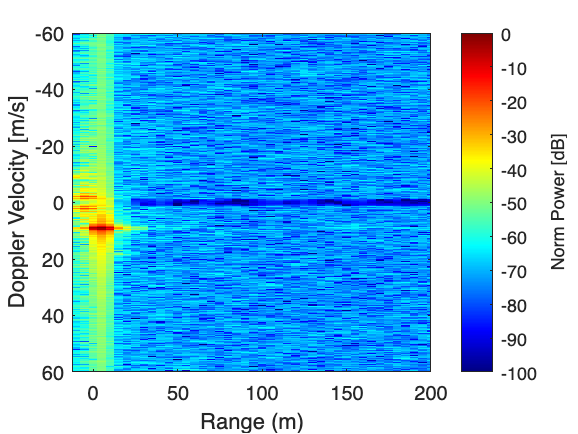

        active.cpi = 0.5; % cohernet proccessing interval (s)
        active.cpi_overlap = 0.8; % overlap between CPIs (watch this - too large will cause slow exceution)
        active.zero_padding = 1; % 1 = none; 2 = 100%
        active.doppler_window = 'Hann';
        active.dynamic_range = 50
        active.velocity_conv = C*(((1/C)/(active.Fc/C)));
        active.max_range_actual = max_range_actual; %1000;
        
        % Create range-Doppler surfaces
        [active.number_cpi,....
            active.pulses_per_cpi,...
            active.range_doppler_slices] = rangeDopplerSlice(MTI_Data,active.cpi,active.PRF,...
            active.cpi_overlap,...
            active.zero_padding,...
            active.doppler_window);
        
        % Create Active Data Range and Doppler Axis
        active.doppler_bins = 1:size(active.range_doppler_slices{1},1);
        active.doppler_axis = linspace(-active.PRF/2,active.PRF/2,size(active.doppler_bins,2));
        active.doppler_velocity_axis = active.doppler_axis * active.velocity_conv;
        active.range_bins_axis = 1:active.range_bins;
        
        % Create video of range-Doppler slices
        video_name = exp_dir + "active_range-Doppler_" + Experiment_ID + ".avi";
        % video_name = "range-Doppler_log_Exp_" + Experiment_ID + ".avi";
        video_title = "Active Radar Capture";
        dynamic_range = +100;
        max_range = 200;
        max_doppler = 60;
        frame_rate = 1/(capture_duration/active.number_cpi);
        createVideo(active.range_doppler_slices,frame_rate,...
            active.range_axis-10,max_range,...
            -active.doppler_velocity_axis,max_doppler,...
            dynamic_range,video_name,video_title);
        
    end

## Passive Processing

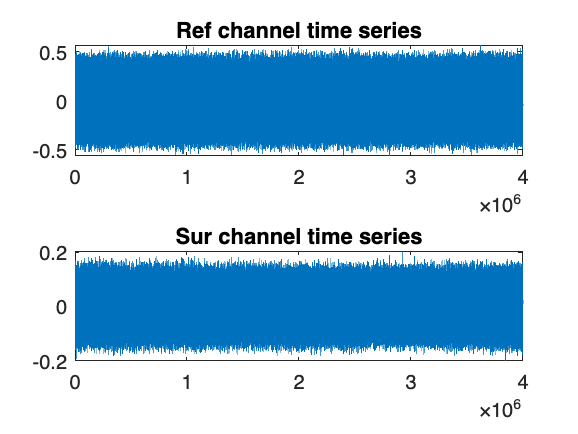

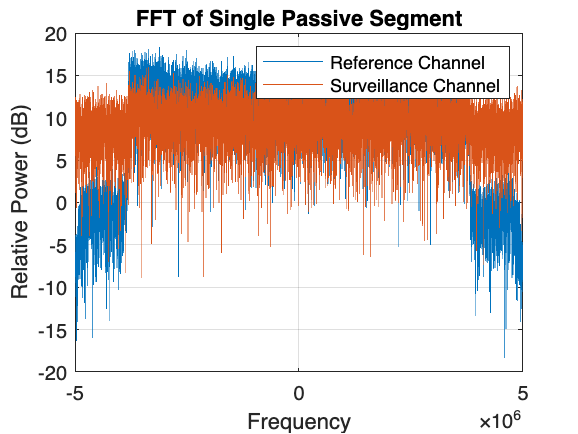

ans = 'Time Domain Based XCORR'

    if process_passive_flag == true
        passive.max_range = 50; % maximum number of range bins - xcorr shifts.
        passive.range_zero_padding = 1; % 1 = none, 2 = 100%
        passive.td_corr = true; % true = time domain xcorr; false = freq domain xcorr
        passive.seg_s = 1000; % number of segments per second - analagos to PRF.
        passive.seg_percent = 100; % % of segment used for xcorr.
        
        % load signal and split ref and sur
        file_location = exp_dir + 'passive_' + Experiment_ID;
        [ref_channel, sur_channel]  = load_passive_data(file_location);
        % Plot time domain signals
        figure
        fig = subplot(2,1,1);
        plot(real(ref_channel(1:4000000)));
        title("Ref channel time series");
        hold on
        subplot(2,1,2)
        plot(real(sur_channel(1:4000000)))
        title("Sur channel time series");
        fig_name = exp_dir + "Time Domain Signals_" + Experiment_ID + ".jpg";
        saveas(fig,fig_name,'jpeg')
        
        % Add Noise to Passive Radar
        noisy_sur_channel= awgn(sur_channel,-2,'measured');
        
        % Batch process data and cross correlate
        [ref_matrix ,self_ambg_matrix, cc_matrix] = passive_batch_process(ref_channel,noisy_sur_channel,passive.seg_s,passive.seg_percent,passive.Fs,passive.max_range,exp_dir,passive.range_zero_padding,passive.td_corr);
        save(exp_dir + 'passive_matrix','cc_matrix')
        
        %     % RTI Plot
        %         RTI_plot= transpose(10*log10(abs(cc_matrix./max(cc_matrix(:)))));
        %         Range_bin = linspace(0,passive.max_range,size(cc_matrix,1));
        %         time_axis = linspace(0,capture_duration,size(cc_matrix,2));
        %         figure
        %         fig = imagesc(Range_bin,time_axis,RTI_plot,[-50,0]);
        %             grid on
        %             colorbar
        %             ylabel('Time (Sec)')
        %             xlabel('Range Bin')
        %             fig_title = "Passive RTI - " + Experiment_ID;
        %             title(fig_title);
        %             fig_name = exp_dir + "Passive RTI_" + Experiment_ID + ".jpg";
        %             saveas(fig,fig_name,'jpeg'); saveas(fig,fig_name);
        %
        %       % CAF of entire capture
        %         f_axis = linspace(-passive.seg_s/2,passive.seg_s/2,size(cc_matrix,2));
        %         t_cc_matrix = transpose(cc_matrix);
        %         CAF = fftshift(fft(t_cc_matrix,size(t_cc_matrix,1),1),1);
        %         figure
        %         imagesc(Range_bin,f_axis,10*log10(abs(CAF./max(CAF(:)))),[-50 1]);
        %             ylim([-500 500])
        %             xlim([1 20])
        %             c = colorbar
        %             c.Label.String='Norm Power (dB)'
        %             ylabel('Doppler Shift (Hz)')
        %             xlabel('Range Bin')
        %             title("CAF for entire capture" + Experiment_ID)
        %             fig_name = exp_dir + "CAF for entire capture_" + Experiment_ID + ".jpg";
        %             saveas(fig,fig_name,'jpeg'); saveas(fig,fig_name);
        %
        %      % Spectrogram
        %         int_bins = sum(cc_matrix(2:10,:),1);
        %         r_bin = 1;
        %         l_fft = 256;
        %         pad_factor = 1;
        %         overlap_factor = 0.99;
        %         [spect,f] = spectrogram(int_bins,l_fft,round(l_fft*overlap_factor),l_fft*pad_factor,passive.seg_s,'centered','yaxis');
        %         spect= 10*log10(abs(spect./max(spect(:))));
        %         figure
        %         fig = imagesc(time_axis,f,spect,[-30 0]);
        %             ylim([-500 +500])
        %             c = colorbar
        %             c.Label.String='Norm Power (dB)'
        %             xlabel('Time (Sec)')
        %             % ylabel('Radial Velocity (mph)')
        %             ylabel('Doppler Frequency (Hz)')
        %             fig_title = "Passive Spectrogram :- " + Experiment_ID;
        %             title(fig_title);
        %             fig_name = exp_dir + "Passive Spectrogram_" + Experiment_ID + ".jpg";
        %             saveas(fig,fig_name,'jpeg'); saveas(fig,fig_name);
        %

## Proccess Passive data into Range-Doppler Slices

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

fig =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [616 498 560 420]
       Units: 'pixels'

  Show all properties


i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

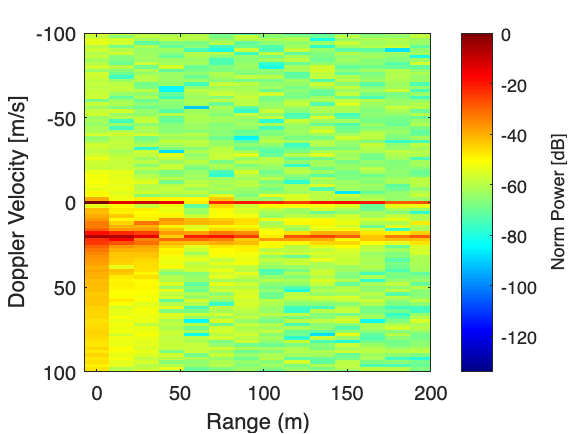

        passive.PRF = passive.seg_s; % seg_s
        passive.cpi = 0.5; % coherent proccessing interval (s)
        passive.cpi_overlap = 0.8; % overlap between CPIs (watch this - too large will cause slow exceution)
        passive.doppler_window = 'Blackman-Harris';
        passive.dopp_zero_padding = 1;
        passive.dynamic_range = +50;
        passive.range_bin_size = (1/passive.Fs)/passive.range_zero_padding * C/2;
        passive.max_range_m = passive.max_range*passive.range_bin_size;
        % Create range-Doppler surfaces
        [passive.number_cpi,...
            passive.pulses_per_cpi,...
            passive.range_doppler_slices] = rangeDopplerSlice(cc_matrix,passive.cpi,passive.PRF,...
            passive.cpi_overlap,...
            passive.dopp_zero_padding,...
            passive.doppler_window);
        % Create Ambiguity surfaces
        [~,~,passive.self_ambg_slices] = rangeDopplerSlice(self_ambg_matrix,passive.cpi,passive.PRF,...
            passive.cpi_overlap,...
            passive.dopp_zero_padding,...
            passive.doppler_window);
        
        % Create Active Data Range and Doppler Axis
        
        passive.cpi_stride = round(passive.pulses_per_cpi*(1-passive.cpi_overlap)); % number of pulses to stride each for next CPI
        passive.velocity_conv = C*(((1/C)/(passive.Fc/C)));
        passive.no_range_bins = size(cc_matrix,1);
        passive.range_bins = 1:passive.no_range_bins;
        passive.doppler_bins = passive.pulses_per_cpi*passive.dopp_zero_padding+1;
        passive.doppler_axis = linspace(-passive.PRF/2,passive.PRF/2,passive.doppler_bins);
        passive.doppler_velocity_axis = passive.doppler_axis*passive.velocity_conv;
        passive.range_axis = linspace(0,passive.max_range_m,passive.no_range_bins);
        
        
        % create video of Passive range-Doppler slices        
        video_name = exp_dir + "passive_range-Doppler_" + Experiment_ID + ".avi";
        video_title = "Passive Pre-DSI";
        dynamic_range = +inf;
        max_range = 200;
        max_doppler = 100;
        frame_rate = 1/(capture_duration/passive.number_cpi);
        createVideo(passive.range_doppler_slices,frame_rate,...
            passive.range_axis,max_range,...
            passive.doppler_axis,max_doppler,...
            dynamic_range,video_name,video_title);
        %

## Direct Signal Interference Cancellation

set DSI cancellation parameters

ans = "Progress : 1%"

ans = "Progress : 2%"

ans = "Progress : 3%"

ans = "Progress : 3%"

ans = "Progress : 4%"

ans = "Progress : 5%"

ans = "Progress : 5%"

ans = "Progress : 6%"

ans = "Progress : 7%"

ans = "Progress : 7%"

ans = "Progress : 8%"

ans = "Progress : 9%"

ans = "Progress : 9%"

ans = "Progress : 10%"

ans = "Progress : 11%"

ans = "Progress : 12%"

ans = "Progress : 12%"

ans = "Progress : 13%"

ans = "Progress : 14%"

ans = "Progress : 14%"

ans = "Progress : 15%"

ans = "Progress : 16%"

ans = "Progress : 16%"

ans = "Progress : 17%"

ans = "Progress : 18%"

ans = "Progress : 18%"

ans = "Progress : 19%"

ans = "Progress : 20%"

ans = "Progress : 20%"

ans = "Progress : 21%"

ans = "Progress : 22%"

ans = "Progress : 23%"

ans = "Progress : 23%"

ans = "Progress : 24%"

ans = "Progress : 25%"

ans = "Progress : 25%"

ans = "Progress : 26%"

ans = "Progress : 27%"

ans = "Progress : 27%"

ans = "Progress : 28%"

ans = "Progress : 29%"

ans = "Progress : 29%"

ans = "Progress : 30%"

ans = "Progress : 31%"

ans = "Progress : 32%"

ans = "Progress : 32%"

ans = "Progress : 33%"

ans = "Progress : 34%"

ans = "Progress : 34%"

ans = "Progress : 35%"

ans = "Progress : 36%"

ans = "Progress : 36%"

ans = "Progress : 37%"

ans = "Progress : 38%"

ans = "Progress : 38%"

ans = "Progress : 39%"

ans = "Progress : 40%"

ans = "Progress : 40%"

ans = "Progress : 41%"

ans = "Progress : 42%"

ans = "Progress : 43%"

ans = "Progress : 43%"

ans = "Progress : 44%"

ans = "Progress : 45%"

ans = "Progress : 45%"

ans = "Progress : 46%"

ans = "Progress : 47%"

ans = "Progress : 47%"

ans = "Progress : 48%"

ans = "Progress : 49%"

ans = "Progress : 49%"

ans = "Progress : 50%"

ans = "Progress : 51%"

ans = "Progress : 52%"

ans = "Progress : 52%"

ans = "Progress : 53%"

ans = "Progress : 54%"

ans = "Progress : 54%"

ans = "Progress : 55%"

ans = "Progress : 56%"

ans = "Progress : 56%"

ans = "Progress : 57%"

ans = "Progress : 58%"

ans = "Progress : 58%"

ans = "Progress : 59%"

ans = "Progress : 60%"

ans = "Progress : 60%"

ans = "Progress : 61%"

ans = "Progress : 62%"

ans = "Progress : 63%"

ans = "Progress : 63%"

ans = "Progress : 64%"

ans = "Progress : 65%"

ans = "Progress : 65%"

ans = "Progress : 66%"

ans = "Progress : 67%"

ans = "Progress : 67%"

ans = "Progress : 68%"

ans = "Progress : 69%"

ans = "Progress : 69%"

ans = "Progress : 70%"

ans = "Progress : 71%"

ans = "Progress : 72%"

ans = "Progress : 72%"

ans = "Progress : 73%"

ans = "Progress : 74%"

ans = "Progress : 74%"

ans = "Progress : 75%"

ans = "Progress : 76%"

ans = "Progress : 76%"

ans = "Progress : 77%"

ans = "Progress : 78%"

ans = "Progress : 78%"

ans = "Progress : 79%"

ans = "Progress : 80%"

ans = "Progress : 80%"

ans = "Progress : 81%"

ans = "Progress : 82%"

ans = "Progress : 83%"

ans = "Progress : 83%"

ans = "Progress : 84%"

ans = "Progress : 85%"

ans = "Progress : 85%"

ans = "Progress : 86%"

ans = "Progress : 87%"

ans = "Progress : 87%"

ans = "Progress : 88%"

ans = "Progress : 89%"

ans = "Progress : 89%"

ans = "Progress : 90%"

ans = "Progress : 91%"

ans = "Progress : 92%"

ans = "Progress : 92%"

ans = "Progress : 93%"

ans = "Progress : 94%"

ans = "Progress : 94%"

ans = "Progress : 95%"

ans = "Progress : 96%"

ans = "Progress : 96%"

ans = "Progress : 97%"

ans = "Progress : 98%"

ans = "Progress : 98%"

ans = "Progress : 99%"

ans = "Progress : 100%"

ans = "Progress : 100%"

mean_process_time_per_slice = 0.0862

fig =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [616 498 560 420]
       Units: 'pixels'

  Show all properties


i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

i = 106

i = 107

i = 108

i = 109

i = 110

i = 111

i = 112

i = 113

i = 114

i = 115

i = 116

i = 117

i = 118

i = 119

i = 120

i = 121

i = 122

i = 123

i = 124

i = 125

i = 126

i = 127

i = 128

i = 129

i = 130

i = 131

i = 132

i = 133

i = 134

i = 135

i = 136

i = 137

i = 138

i = 139

i = 140

i = 141

i = 142

i = 143

i = 144

i = 145

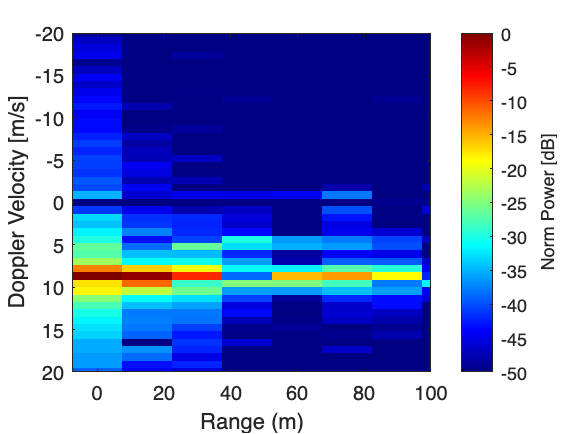

        p = 0.999;        % subtraction parameter - P must be a positive
        % integer less than one to avoid unwanted discontinuities
        % arising from zero values in the range–Doppler surface.
        threshold = 0.005; % cutoff threshold parameter
        max_iterations = 1000; % maximum number of itterations DSI is CLEANed from CAF slice
        number_rbins = size(passive.range_doppler_slices{1},2);
        
        % perform CLEAN based DSI Cancellation
        passive.CLEANed_range_doppler_slices = CLEAN_DSI(passive.range_doppler_slices,...
            passive.self_ambg_slices,...
            ref_matrix,...
            passive.number_cpi,...
            passive.pulses_per_cpi,...
            passive.cpi_stride,...
            passive.dopp_zero_padding,...
            number_rbins,...
            max_iterations,...
            threshold,p,...
            passive.range_axis,passive.doppler_axis);
        
        %   % create video of CLEANed range-Doppler slices
        video_name = exp_dir + "CLEANed_range-Doppler_CLEANed_log_Exp_" + Experiment_ID + ".avi";
        %video_name = "passive_RangeDoppler_CLEANed_log_Exp_" + Experiment_ID + ".avi";
        video_title = "CLEANed Passive Radar Capture";
        dynamic_range = 50;
        max_range = 100;
        max_doppler = 20;
        frame_rate = 1/(capture_duration/passive.number_cpi);
        createVideo(passive.CLEANed_range_doppler_slices,frame_rate,...
            passive.range_axis,max_range,...
            passive.doppler_velocity_axis,max_doppler,...
            dynamic_range,video_name,video_title);
        
    end 
end

toc

Elapsed time is 98.176558 seconds.
